# Plot Error Margins on 2-D Data Sets

`errorbar` creates a line plot of a provided vector and draws both vertical and horizontal error bars at each data point. A vector containing error values determine the lengths of each error bar at the data points, so the total error bar lengths are double the `err` values.

### Create Data With an Error Vector

Create vectors `x` and `y`. Create an error vector the same dimension as `x` and `y`. 

x = 1:10:100;
y = [20 30 45 40 60 65 80 75 95 90];
err = 8*rand(size(y));

### Basic Errorbar 

Plot `y` versus `x`. At each data point, display vertical error bars of random magnitude.

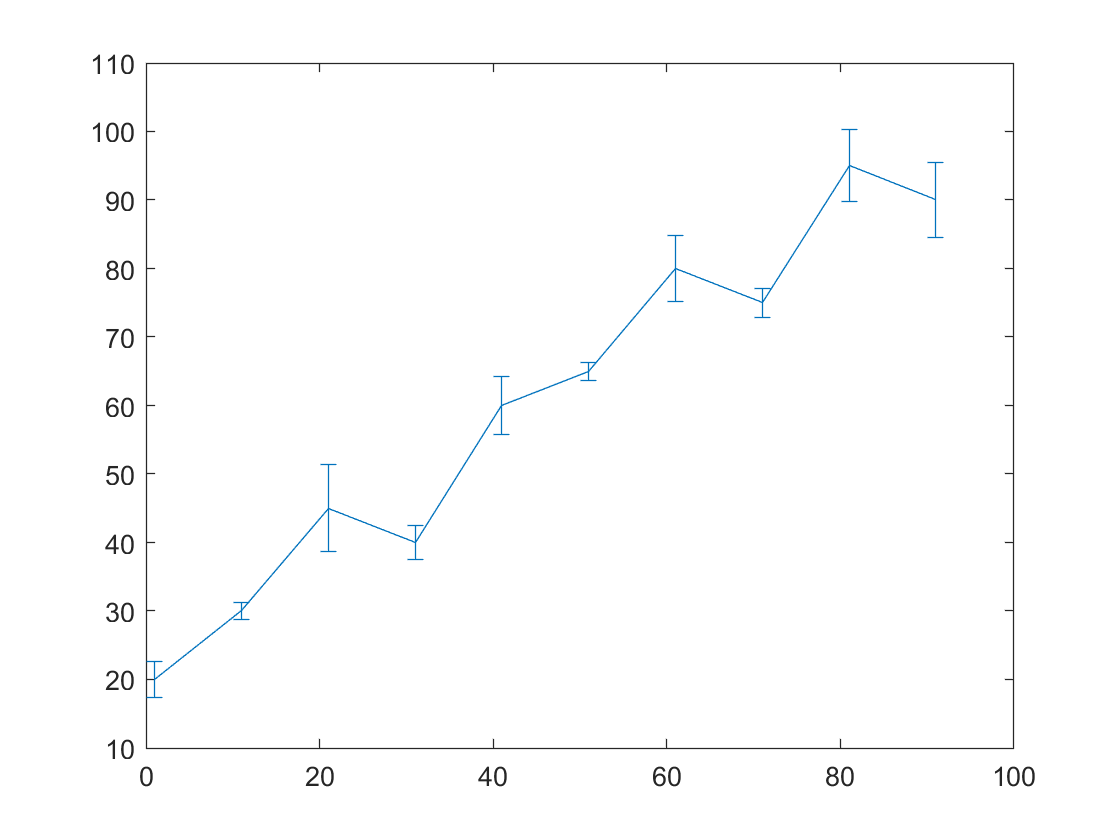

errorbar(x,y,err)

## Customizations 

### Plot Horizontal Error Bars

Create a line plot with horizontal error bars at each data point by specifying `horizontal` in the function call.

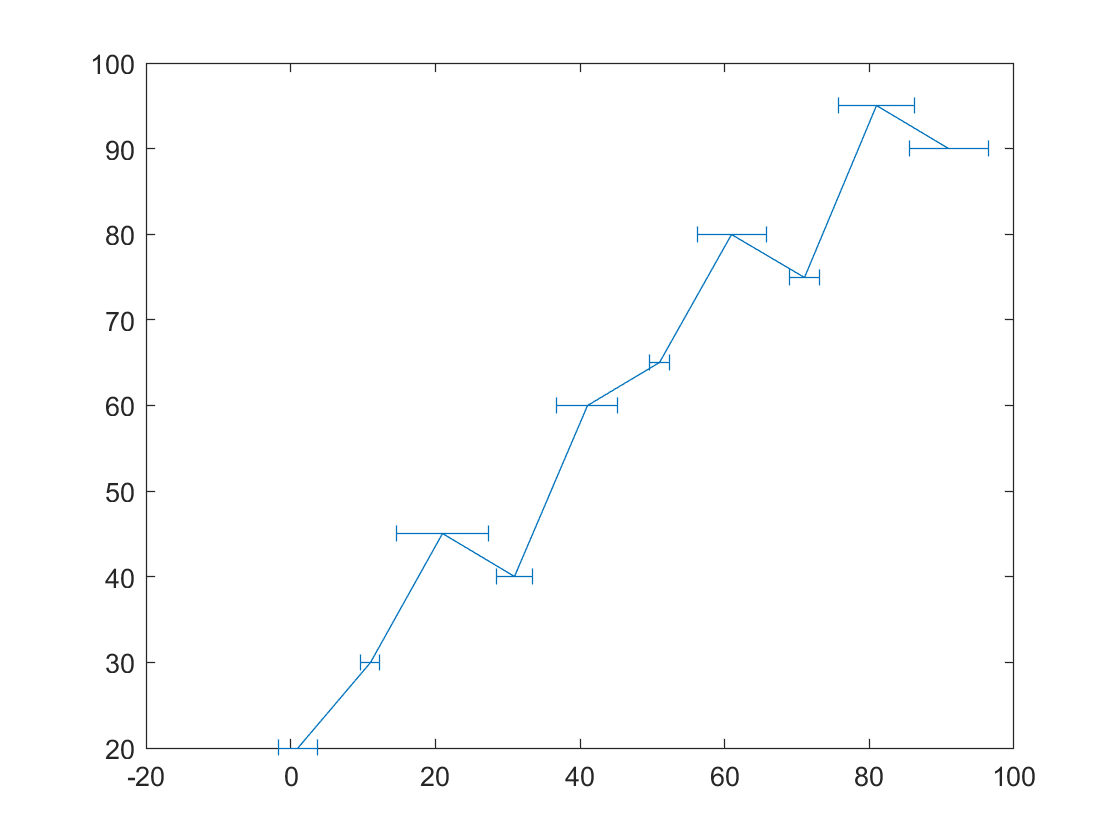

errorbar(x,y,err,"horizontal")

### Specify Error Bar Lengths in All Directions

Display both vertical and horizontal error bars at each data point. Control the lower and upper lengths of the vertical error bars using the `yneg` and `ypos` input argument options, respectively. Control the left and right lengths of the horizontal error bars using the `xneg` and `xpos` input argument options, respectively. 

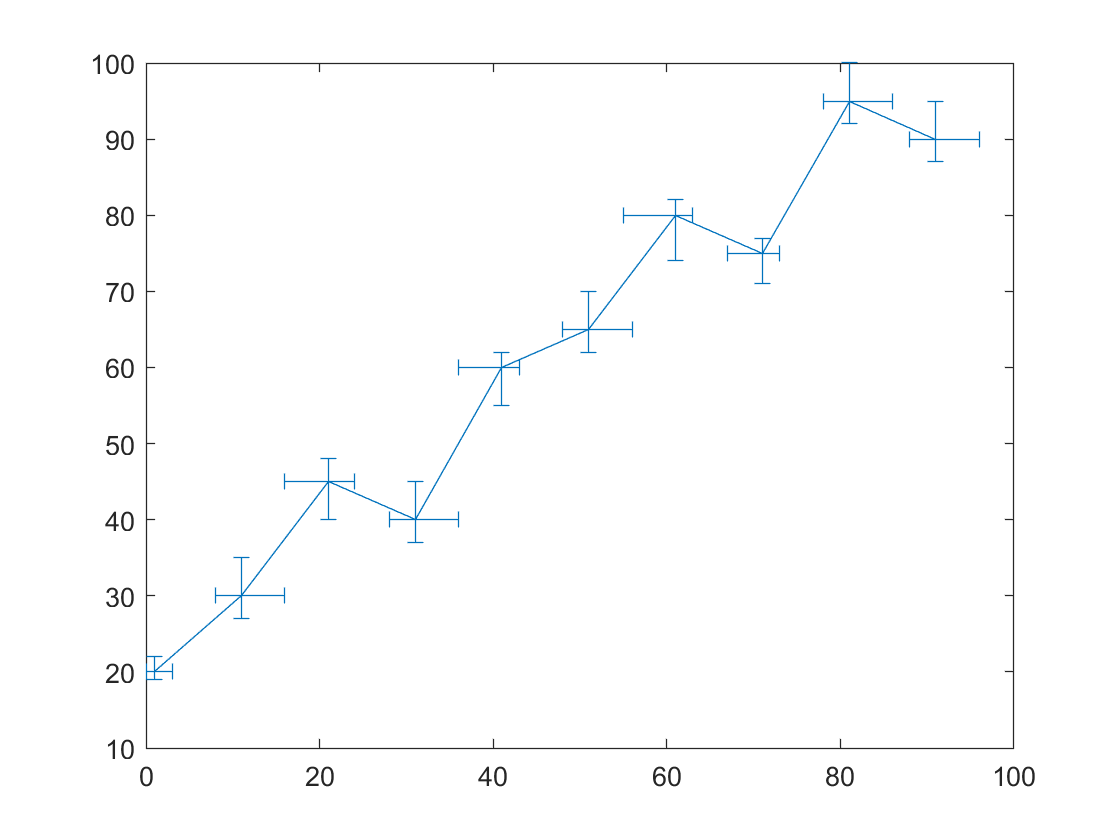

x = 1:10:100;
y = [20 30 45 40 60 65 80 75 95 90];
yneg = [1 3 5 3 5 3 6 4 3 3];
ypos = [2 5 3 5 2 5 2 2 5 5];
xneg = [1 3 5 3 5 3 6 4 3 3];
xpos = [2 5 3 5 2 5 2 2 5 5];
errorbar(x,y,yneg,ypos,xneg,xpos)

### Customize Line and Marker Settings

To maintian a readable plot, represent each data point as a red dot and increase the *LineWidth *property for more visible bars.

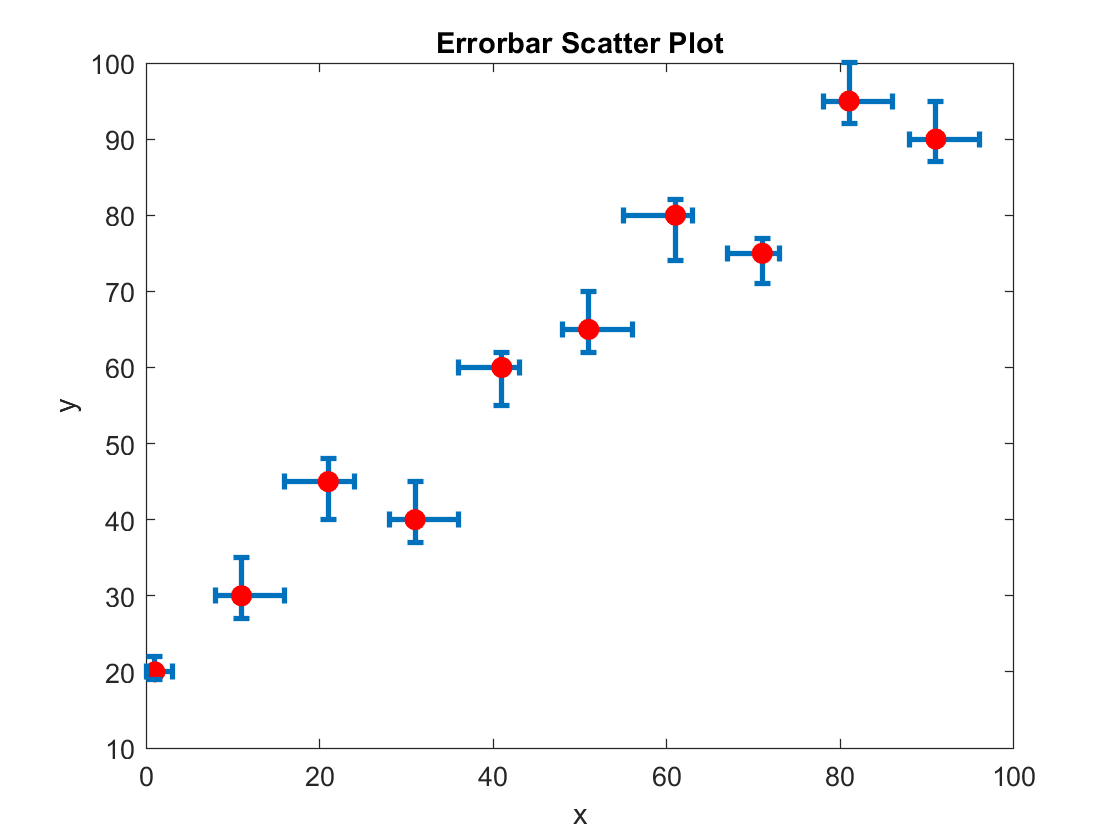

PointColor = "red";
LineWidth = 2;
e = errorbar(x,y,yneg,ypos,xneg,xpos, ...
    'o',...                                         % specify data appearance as a point
    "MarkerEdgeColor",PointColor,...                % specify the point marker color
    "MarkerFaceColor",PointColor,...                % specify the point marker color
    "LineWidth", LineWidth);                        % specify the line thickness

title("Errorbar Scatter Plot")
xlabel('x')
ylabel('y')

## Additional Information

### Get All Coneplot Properties

Graphics objects in MATLAB have many properties. To see all the properties of a coneplot, uncomment the following code

% get(e)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[errorbar](https://www.mathworks.com/help/matlab/ref/errorbar.html)